# Hurricane Harvey Analysis

### **Table of Contents**

- Import the Data

- States Impacted by harvey

- Dates that Hurricane Harvey happened in between

- Two States Most Impacted by Harvey

- Table of Events for Two Most Impacted States

- Figure of Event Types

- Figure of Event Locations

- Three Counties with Most Events in TEXAS

- Three Counties with Most Events in LOUISIANA

- Three Counties with Highest Property Cost in TEXAS

- Three Counties with Highest Property Cost in LOUISIANA

- Recommendations

## Background and Scope

### Import the Data

Imported: 

- State

- Event_Type

- CZ_Name

- Begin_Date_Time

- End_Date_Time

- Property_Cost

- Begin_Lat

- Begin_Lon

- End_Lat

- End_Lon

uiimport("StormEvents_2017_finalProject.csv")

The imported data as been selected manually on the import wizard.

### States Impacted by harvey

    In order to filter the data to know which data is related to hurricane Harvey we need to filter thouse data including only these states.

- Arkansas

- Kentucky

- Louisiana

- Mississippi

- North Carolina

- Tennessee

- Texas.

StormEvents2017finalProject = StormEvents2017finalProject(StormEvents2017finalProject.State == 'ARKANSAS' ...
    | StormEvents2017finalProject.State == 'KENTUCKY' | StormEvents2017finalProject.State == 'LOUISIANA' ...
    | StormEvents2017finalProject.State == 'MISSISSIPPI' | StormEvents2017finalProject.State == 'NORTH CAROLINA' ...
    | StormEvents2017finalProject.State == 'TENNESSEE' | StormEvents2017finalProject.State == 'TEXAS', :)

StormEvents2017finalProject = 10667×10 table
        State            Event_Type         CZ_Name        Begin_Date_Time         End_Date_Time       Property_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon
    ______________    _________________    __________    ___________________    ___________________    _____________    _________    _________    _______    _______

    ARKANSAS          Hail                 FRANKLIN      2017-04-26 07:57:00    2017-04-26 07:57:00            0         35.297       -94.038     35.297     -94.038
    TEXAS             Hail                 HENDERSON     2017-05-03 14:06:00    2017-05-03 14:06:00         1000       

### Dates that Hurricane Harvey happened in between

    I will asume that assume that Harvey related events occurred only from the 17th of August to the 3rd of September.

StormEvents2017finalProject = StormEvents2017finalProject( ...
    StormEvents2017finalProject.Begin_Date_Time >= datetime('2017-08-17 00:00:00') ...
    & StormEvents2017finalProject.End_Date_Time < datetime('2017-09-04 00:00:00') , :);

    At the end we will get the following table

StormEvents2017finalProject

StormEvents2017finalProject = 573×10 table
        State            Event_Type          CZ_Name        Begin_Date_Time         End_Date_Time       Property_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon
    ______________    _________________    ___________    ___________________    ___________________    _____________    _________    _________    _______    _______

    TEXAS             Tropical Storm       MONTGOMERY     2017-08-25 12:00:00    2017-08-30 00:00:00         7e+09           NaN           NaN        NaN         NaN
    MISSISSIPPI       Strong Wind          LOWNDES        2017-09-01 01:00:00    2017-09-01 01:00:00          5000    

### Two States Most Impacted by Harvey

    Here we will find the two most states that have the heighest property cost

Table = groupsummary(StormEvents2017finalProject, 'State', 'sum', 'Property_Cost'); % finding the total property cost by state
Table = sortrows(Table, 'sum_Property_Cost', "descend") % sort the rows in a descending order according to the sum_Property_Cost coloumn

T = 7×3 table
        State         GroupCount    sum_Property_Cost
    ______________    __________    _________________

    TEXAS                272           7.7427e+10    
    LOUISIANA             85           7.5277e+07    
    NORTH CAROLINA        59           1.2339e+07    
    MISSISSIPPI           39             9.15e+05    
    TENNESSEE             46             5.04e+05    
    KENTUCKY              20             4.35e+05    
    ARKANSAS              52                61000    


Table([1, 2], :) % display the first two rows

ans = 2×3 table
      State      GroupCount    sum_Property_Cost
    _________    __________    _________________

    TEXAS           272           7.7427e+10    
    LOUISIANA        85           7.5277e+07    


    From here we can see that the two most impacted states are TEXAS and LOUISIANA.

### Table of Events for Two Most Impacted States

    Here we will create a table with only the rows which contains the states TEXAS and LOUISIANA and group them with the events most frequent

clearvars -except StormEvents2017finalProject % delete the variables T and ans
Table = StormEvents2017finalProject(StormEvents2017finalProject.State == "TEXAS" ...
    | StormEvents2017finalProject.State == 'LOUISIANA', :);
Table = groupsummary(Table, "Event_Type");
Table = sortrows(Table, 'GroupCount', "descend");
Table

T = 11×2 table
       Event_Type        GroupCount
    _________________    __________

    Flash Flood             179    
    Tropical Storm           44    
    Tornado                  33    
    Heat                     30    
    Thunderstorm Wind        27    
    Flood                    17    
    Storm Surge/Tide         10    
    Hurricane                 9    
    Funnel Cloud              3    
    Hail                      3    
    Heavy Rain                2    


clear Table

    From the table above we can see that the events that impactes these states from most frequent to least frequent are:

- Flash Flood

- Tropical Storm

- Tornado

- Heat

- Thunderstorm Wind

- Flood

- Strorm Surge

- Hurricane

- Funnel Cloud

## Visualizations

### Figure of Event Types

    First we will show a visualization for the event type and number of occurancies of events that occured in TEXAS and LOUISIANA.

#### TEXAS and LOUISIANA

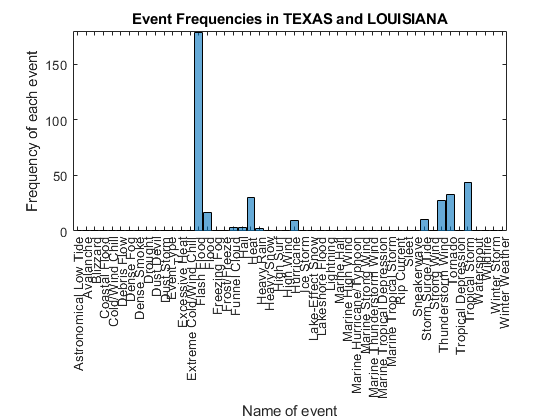

Table = StormEvents2017finalProject(StormEvents2017finalProject.State == "TEXAS" ...
    | StormEvents2017finalProject.State == 'LOUISIANA', :);
histogram(Table.Event_Type)

title('Event Frequencies in TEXAS and LOUISIANA')
xlabel('Name of event')
ylabel('Frequency of each event')

Showing a table of frequencies to better interpret the data

Table = groupsummary(Table, 'Event_Type');
Table = sortrows(Table, 'GroupCount', 'descend');
Table

T = 11×2 table
       Event_Type        GroupCount
    _________________    __________

    Flash Flood             179    
    Tropical Storm           44    
    Tornado                  33    
    Heat                     30    
    Thunderstorm Wind        27    
    Flood                    17    
    Storm Surge/Tide         10    
    Hurricane                 9    
    Funnel Cloud              3    
    Hail                      3    
    Heavy Rain                2    


#### TEXAS

TEXAS Histogram to show the frequencies

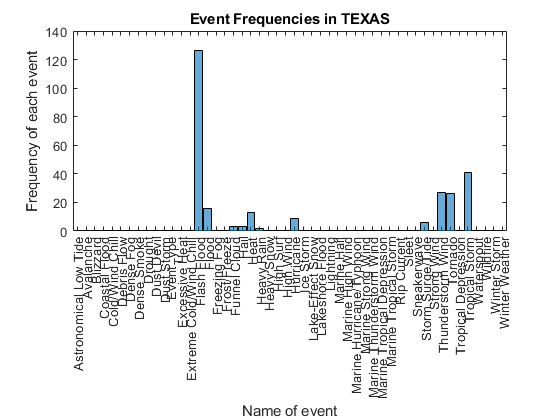

clear Table
Table = StormEvents2017finalProject(StormEvents2017finalProject.State == "TEXAS", :);
histogram(Table.Event_Type)

title('Event Frequencies in TEXAS')
xlabel('Name of event')
ylabel('Frequency of each event')

Showing a table of frequencies to better interpret the data

Table = groupsummary(Table, 'Event_Type');
Table = sortrows(Table, 'GroupCount', 'descend');
Table

T = 11×2 table
       Event_Type        GroupCount
    _________________    __________

    Flash Flood             126    
    Tropical Storm           41    
    Thunderstorm Wind        27    
    Tornado                  26    
    Flood                    16    
    Heat                     13    
    Hurricane                 9    
    Storm Surge/Tide          6    
    Funnel Cloud              3    
    Hail                      3    
    Heavy Rain                2    


#### LOUISIANA

LOUISIANA Histogram to show the frequencies

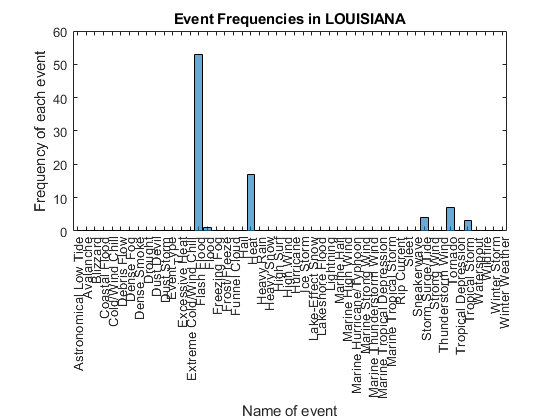

clear Table
Table = StormEvents2017finalProject(StormEvents2017finalProject.State == "LOUISIANA", :);
histogram(Table.Event_Type)

title('Event Frequencies in LOUISIANA')
xlabel('Name of event')
ylabel('Frequency of each event')

Showing a table of frequencies to better interpret the data

Table = groupsummary(Table, 'Event_Type');
Table = sortrows(Table, 'GroupCount', 'descend');
Table

T = 6×2 table
       Event_Type       GroupCount
    ________________    __________

    Flash Flood             53    
    Heat                    17    
    Tornado                  7    
    Storm Surge/Tide         4    
    Tropical Storm           3    
    Flood                    1    


clear Table

### Figure of Event Locations

Table = StormEvents2017finalProject(StormEvents2017finalProject.State == "TEXAS" ...
    | StormEvents2017finalProject.State == 'LOUISIANA', :);
Table = Table(~isnan(Table.Begin_Lat), :);
Table = Table(~isnan(Table.Begin_Lon), :);
Table = Table(~isnan(Table.End_Lat), :);
Table = Table(~isnan(Table.End_Lon), :);

To calculate the are of each marker I will use a calculation in one of the examples in the [documentation](https://www.mathworks.com/help/matlab/ref/geoscatter.html)

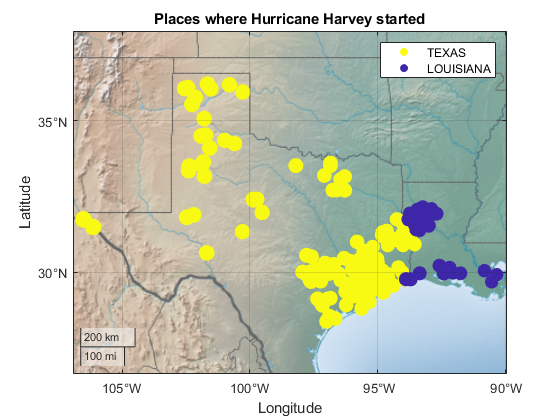

Table.A_Begin = 101 + 100*(sind(2*Table.Begin_Lon));
Table.A_End = 101 + 100*(sind(2*Table.End_Lon));

TEXAS = Table(Table.State == "TEXAS", :);
LOUISIANA = Table(Table.State == "LOUISIANA", :);

clear Table

geoscatter(TEXAS.Begin_Lat,TEXAS.Begin_Lon, TEXAS.A_Begin, TEXAS.State, 'filled')
hold on
geoscatter(LOUISIANA.Begin_Lat,LOUISIANA.Begin_Lon, LOUISIANA.A_Begin, LOUISIANA.State, 'filled')
hold off
title('Places where Hurricane Harvey started')
legend('TEXAS', 'LOUISIANA')
geobasemap colorterrain

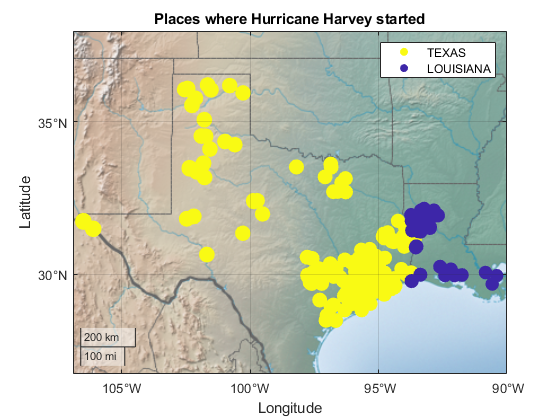

geoscatter(TEXAS.End_Lat,TEXAS.End_Lon, TEXAS.A_End, TEXAS.State, 'filled')
hold on
geoscatter(LOUISIANA.End_Lat,LOUISIANA.End_Lon, LOUISIANA.A_End, LOUISIANA.State, 'filled')
hold off
title('Places where Hurricane Harvey started')
legend('TEXAS', 'LOUISIANA')
geobasemap colorterrain

clear TEXAS
clear LOUISIANA

## Analysis

### Three Counties with Most Events in TEXAS

#### Table of the Three Counties with Most Events

Table = StormEvents2017finalProject(StormEvents2017finalProject.State == 'TEXAS', :);
Table = groupsummary(Table, 'CZ_Name');
Table = sortrows(Table, 'GroupCount', 'descend')

T = 95×2 table
     CZ_Name      GroupCount
    __________    __________

    HARRIS            21    
    GALVESTON         17    
    FORT BEND         13    
    ANGELINA          12    
    BRAZORIA          12    
    SABINE            12    
    BASTROP            9    
    CHAMBERS           8    
    CALDWELL           7    
    MONTGOMERY         6    
    MATAGORDA          5    
    WHARTON            5    
    CALHOUN            4    
    FAYETTE            4    
    JEFFERSON          4    
    LIBERTY            4    


Table = Table([1, 2, 3], :);
Table

T = 3×2 table
     CZ_Name     GroupCount
    _________    __________

    HARRIS           21    
    GALVESTON        17    
    FORT BEND        13    


clear Table

### Three Counties with Most Events in LOUISIANA

#### Table of the Three Counties with Most Events

Table = StormEvents2017finalProject(StormEvents2017finalProject.State == 'LOUISIANA', :);
Table = groupsummary(Table, 'CZ_Name');
Table = sortrows(Table, 'GroupCount', 'descend')

T = 30×2 table
      CZ_Name       GroupCount
    ____________    __________

    NATCHITOCHES        21    
    SABINE              15    
    RED RIVER            9    
    WINN                 6    
    VERMILION            4    
    CAMERON              3    
    DE SOTO              3    
    UNION                2    
    ACADIA               1    
    BEAUREGARD           1    
    BIENVILLE            1    
    BOSSIER              1    
    CADDO                1    
    CALCASIEU            1    
    CALDWELL             1    
    CLAIBORNE            1    


Table = Table([1, 2, 3], :);
Table

T = 3×2 table
      CZ_Name       GroupCount
    ____________    __________

    NATCHITOCHES        21    
    SABINE              15    
    RED RIVER            9    


clear Table

### Three Counties with Highest Property Cost in TEXAS

#### Table of the Three Counties with Highest Property Cost

Table = StormEvents2017finalProject(StormEvents2017finalProject.State == 'TEXAS', :);
Table = groupsummary(Table, 'CZ_Name', 'sum', 'Property_Cost');
Table = sortrows(Table, 'sum_Property_Cost', 'descend')

T = 95×3 table
      CZ_Name       GroupCount    sum_Property_Cost
    ____________    __________    _________________

    GALVESTON           17                2e+10    
    FORT BEND           13           1.6004e+10    
    MONTGOMERY           6              1.4e+10    
    HARRIS              21           1.0001e+10    
    JEFFERSON            4                3e+09    
    BRAZORIA            12           2.0008e+09    
    ARANSAS              2             1.95e+09    
    ORANGE               2              1.5e+09    
    NUECES               2              1.3e+09    
    WALKER               4              1.2e+09    
    LIBERTY              4                1e+09    
    SAN JACINTO          3                7e+08    
    HARDIN               1                6e+08    
    POLK                 2                6e+08    
    SAN PATRICIO         2             5.02e+08   

Table = Table([1, 2, 3], :);
Table

T = 3×3 table
     CZ_Name      GroupCount    sum_Property_Cost
    __________    __________    _________________

    GALVESTON         17                2e+10    
    FORT BEND         13           1.6004e+10    
    MONTGOMERY         6              1.4e+10    


clear Table

### Three Counties with Highest Property Cost in LOUISIANA

#### Table of the Three Counties with Highest Property Cost

Table = StormEvents2017finalProject(StormEvents2017finalProject.State == 'LOUISIANA', :);
Table = groupsummary(Table, 'CZ_Name', 'sum', 'Property_Cost');
Table = sortrows(Table, 'sum_Property_Cost', 'descend')

T = 30×3 table
      CZ_Name       GroupCount    sum_Property_Cost
    ____________    __________    _________________

    CALCASIEU           1                6e+07     
    BEAUREGARD          1              1.5e+07     
    ACADIA              1                2e+05     
    CAMERON             3                72000     
    VERMILION           4                 5000     
    BIENVILLE           1                    0     
    BOSSIER             1                    0     
    CADDO               1                    0     
    CALDWELL            1                    0     
    CLAIBORNE           1                    0     
    DE SOTO             3                    0     
    EAST CAMERON        1                    0     
    GRANT               1                    0     
    IBERIA              1                    0     
    JACKSON             1                    0    

Table = Table([1, 2, 3], :);
Table

T = 3×3 table
     CZ_Name      GroupCount    sum_Property_Cost
    __________    __________    _________________

    CALCASIEU         1                6e+07     
    BEAUREGARD        1              1.5e+07     
    ACADIA            1                2e+05     


clear Table

## Conclusions and Recommendations

### Recommendations

    If the people effected by the hurricane agreed to go to a different state then they should be sent to any state not in this table.

    If the people did not agree to go to a different state then they should go to any countie not in this table if they are from TEXAS if it existed.

    If the people did not agree to go to a different state then they should go to any countie not in this table if they are from LOUISIANA if it existed.

clear StormEvents2017finalProject